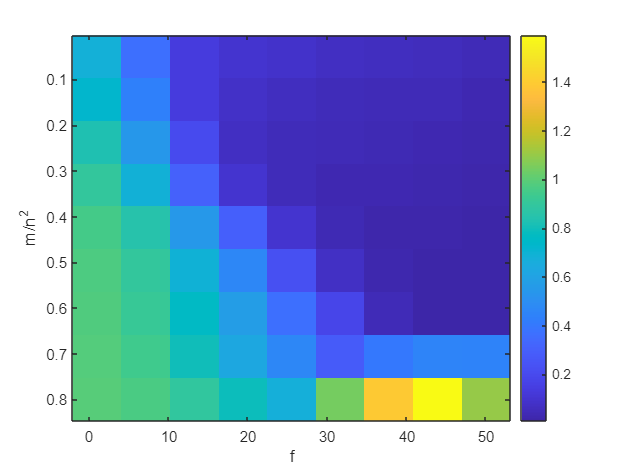

U = RandOrthMat(200);
V = RandOrthMat(200);
R = [1, 2, 3, 5, 10, 15, 20, 25, 50];
F = [0.05, 0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8];
RMSE = double(zeros(9,9));
for r = 1:9
    X = U(:,1:R(r))*V(:,1:R(r))';
    for f = 1:9
        m = F(f)*200*200;
        sigma = (zeros(200,200));
        sigma(randperm(numel(sigma), m)) = 1;
        X1 = X.*sigma;
        X1 = X1 + normrnd(0,(5e-7*(sum(abs(X1),"all"))),200,200);
        recovered = SVT(X1, sigma, 1, 200,200);
        rmse = norm(recovered-X,"fro")/(norm(X,'fro'));
        RMSE(r,f) = rmse;
    end
end
imagesc(R,F,RMSE);
colorbar;
xlabel('f');
ylabel('m/n^2')